clear
addpath("..\data\geojsonR01\")
addpath("..\data\matlabMobile\")

% センサーデータの読み込みとまとめ
load("himeji2shinosaka.mat")

sensor = synchronize(Acceleration,AngularVelocity,MagneticField,Orientation,Position,'union','previous')

sensor = 630851×18 timetable
           Timestamp            X_Acceleration    Y_Acceleration    Z_Acceleration    X_AngularVelocity    Y_AngularVelocity    Z_AngularVelocity    X_MagneticField    Y_MagneticField    Z_MagneticField    X_Orientation    Y_Orientation    Z_Orientation    latitude    longitude    altitude    speed    course    hacc
    ________________________    ______________    ______________    ______________    _________________    _________________    _________________    _______________    _______________    _______________    _____________    _____________    _____________    ________    _________    ________    _____    ______    ____

    03-6月-2019 19:05:28.999            NaN               NaN              NaN                 NaN                  NaN                   NaN                NaN                NaN                NaN              NaN               NaN              NaN        34.827      134.69       18.871       0      258.4      10 
    03-6月-2019 19

sensor = rmmissing(sensor);

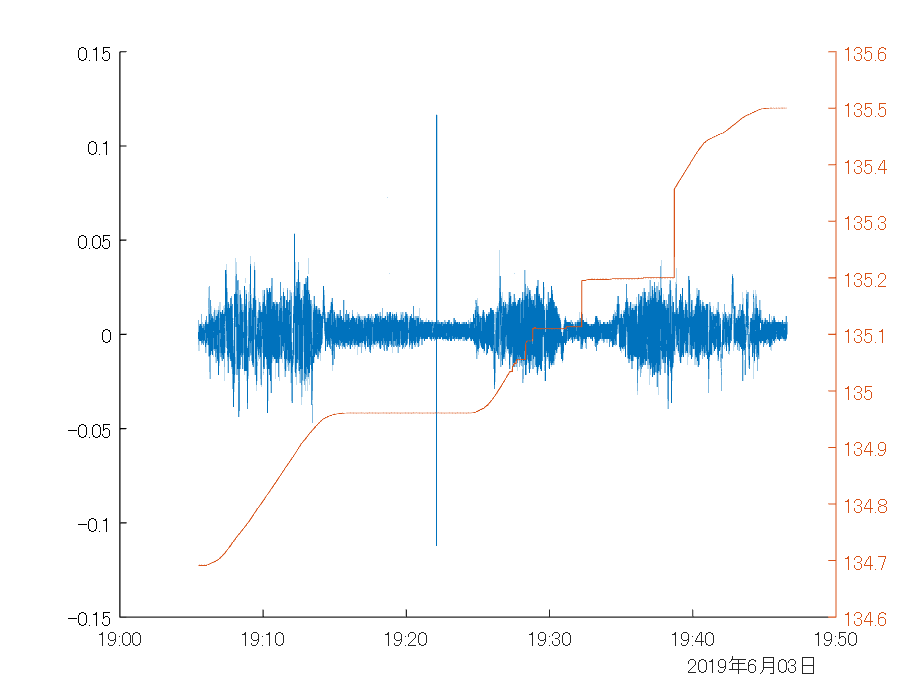

figure
hold on
plot(sensor.Timestamp,sensor.Y_AngularVelocity)
yyaxis right
plot(sensor.Timestamp,sensor.longitude)
hold off

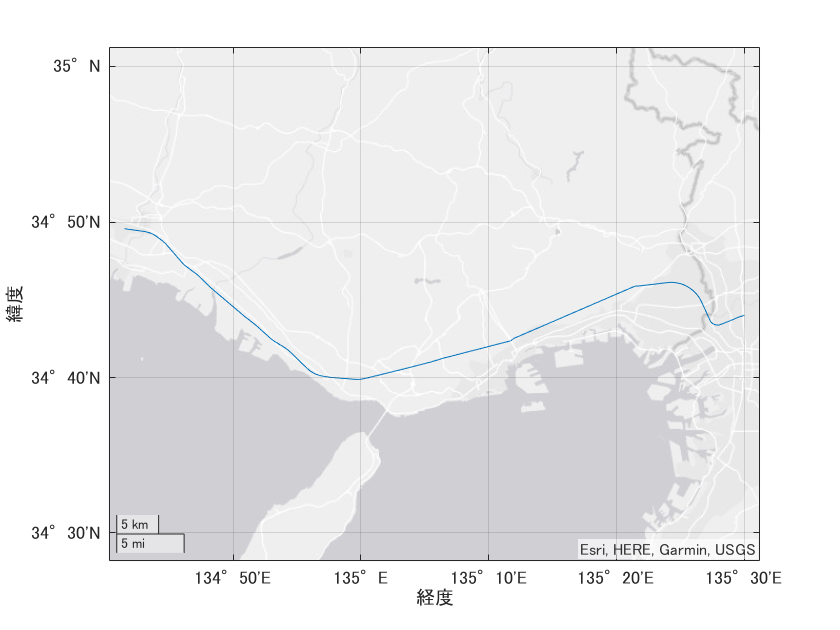

geoplot(sensor.latitude,sensor.longitude)

dt = seconds(sensor.Timestamp(2:end)-sensor.Timestamp(1:end-1))

dt =     0.0040
    0.0030
    0.0030
    0.0040
    0.0030
    0.0030
    0.0040
    0.0030
    0.0030
    0.0040


vel = zeros(length(sensor.Timestamp),1);
for ii = 2:length(dt)+1
    vel(ii) = -sensor.Y_Acceleration(ii) * dt(ii-1) + vel(ii-1);
end
vel = detrend(vel)

vel =   -37.4279
  -37.4279
  -37.4280
  -37.4280
  -37.4280
  -37.4281
  -37.4281
  -37.4281
  -37.4281
  -37.4282


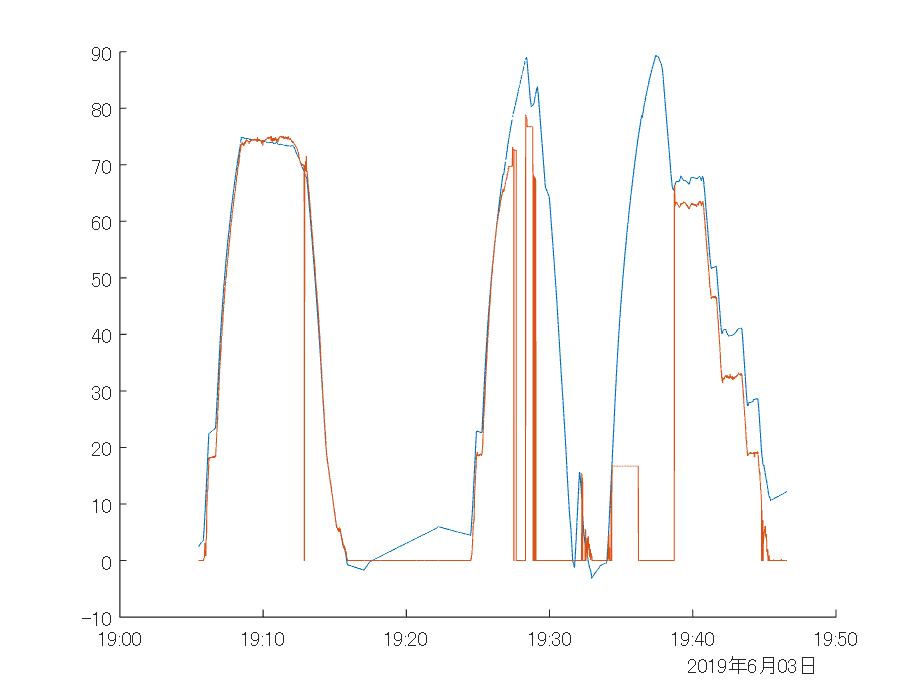

vel = vel + 40;
figure
hold on
plot(sensor.Timestamp,vel)
plot(sensor.Timestamp,sensor.speed)
hold off